# Data Exploration

In this notebook, we will explore the .csv data corresponding to the dataset which has already been processed with FreeSurfer by us. The aggregated volumes of the different brain regions for each subject is listed in the csv file in the data folder. We will use this to get a first overview of the data with plotting.

Load the data from the .csv file:

[file_name, file_path] = uigetfile(".csv", "Point to the .csv file here.");
measurements = readtable(fullfile(file_path, file_name));

% There's no need to convert age to float - it already is, through
% readtable.

% Optionally convert Sex to categorical.
measurements.Sex = categorical(measurements.Sex);

plotcols = setdiff(measurements.Properties.VariableNames, {'Age', 'Sex', 'Subject'})

plotcols = 1×45 cell array
    {'Brain_Stem'}    {'CC_Anterior'}    {'CC_Central'}    {'CC_Mid_Anterior'}    {'CC_Mid_Posterior'}    {'CC_Posterior'}    {'CSF'}    {'Left_Accumbens_area'}    {'Left_Amygdala'}    {'Left_Caudate'}    {'Left_Cerebellum_Cortex'}    {'Left_Cerebellum_White_Matter'}    {'Left_Hippocampus'}    {'Left_Inf_Lat_Vent'}    {'Left_Lateral_Ventricle'}    {'Left_Pallidum'}    {'Left_Putamen'}    {'Left_Thalamus_Proper'}    {'Left_VentralDC'}    {'Left_WM_hypointensities'}    {'Left_choroid_plexus'}    {'Left_non_WM_hypointensities'}    {'Left_vessel'}    {'Optic_Chiasm'}    {'Right_Accumbens_area'}    {'Right_Amygdala'}    {'Right_Caudate'}    {'Right_Cerebellum_Cortex'}    {'Right_Cerebellum_White_Matter'}    {'Right_Hippocampus'}    {'Right_Inf_Lat_Vent'}    {'Right_Lateral_Ventricle'}    {'Right_Pallidum'}    {'Right_Putamen'}    {'Right_Thalamus_Proper'}    {'Right_VentralDC'}    {'Right_WM_hypointensities'}    {'Right_choroid_plexus'}    {'Right_non_WM_hypointen

Plot the volumes of the different brain regions across age.

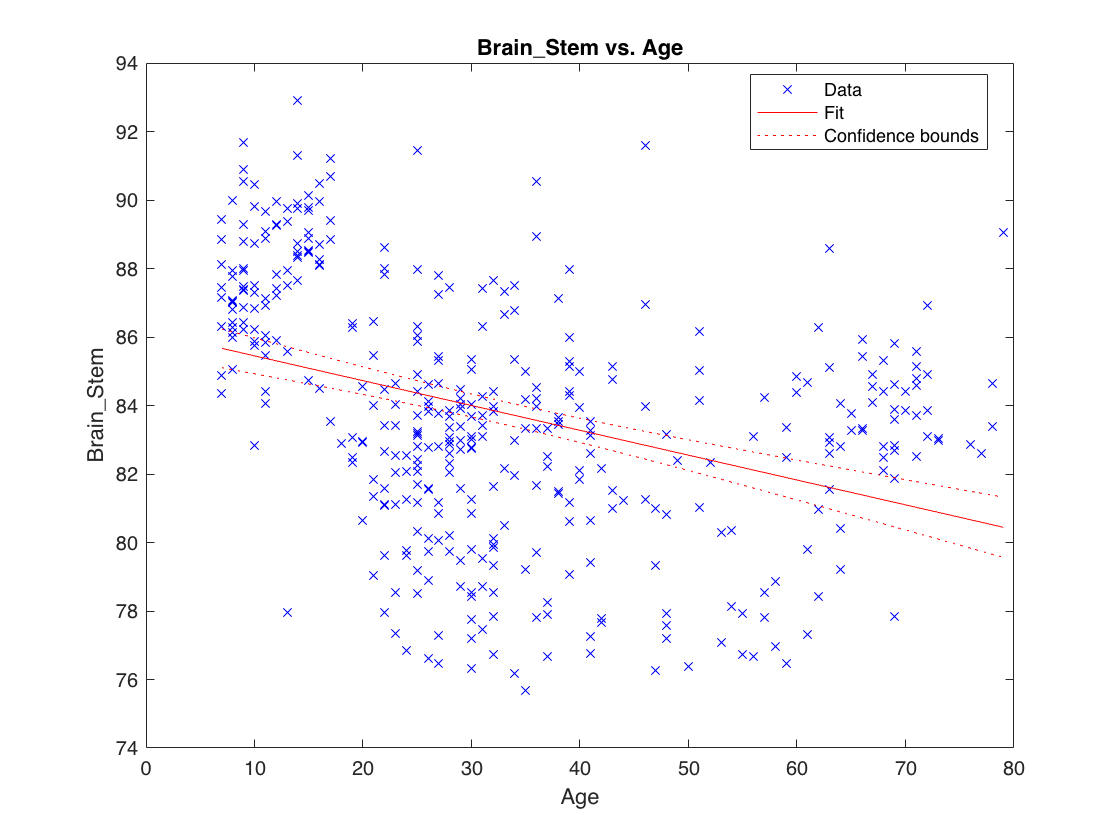

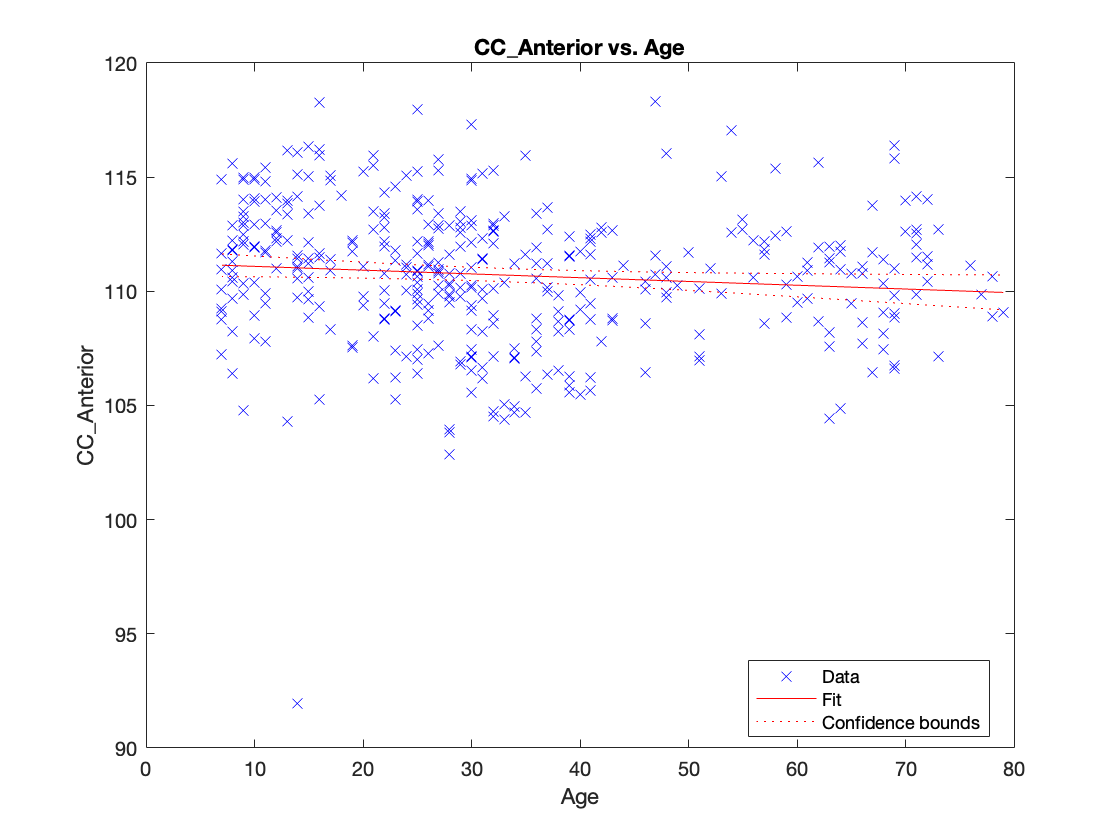

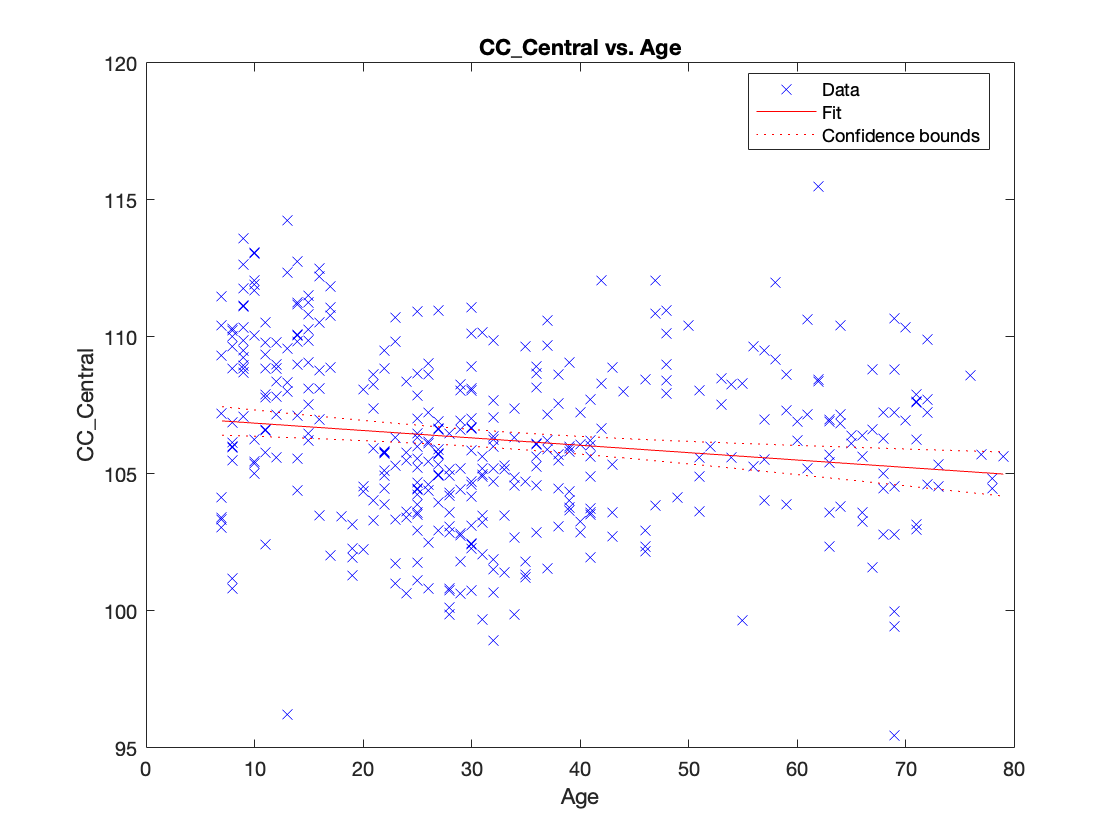

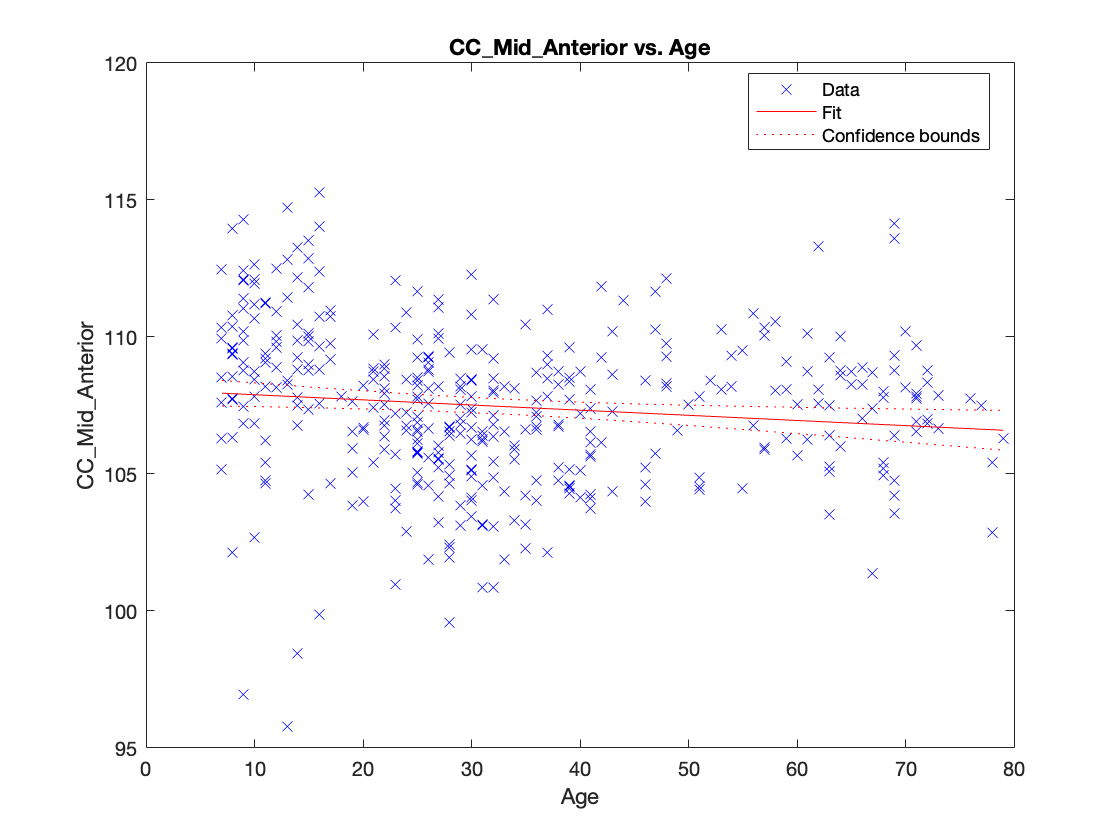

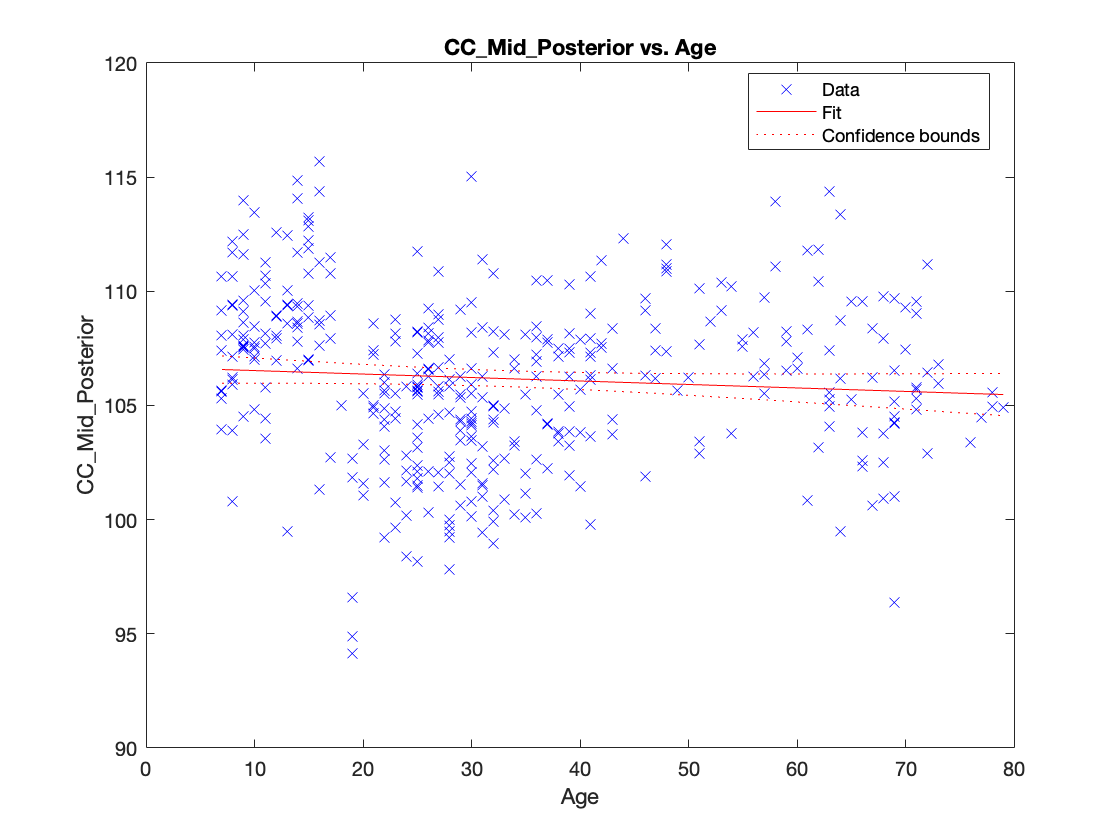

for idx = 1:5 %numel(plotcols) % uncomment this to plot all the regions - showing 5 for now.
    col = plotcols(idx);
    mdl = fitlm(measurements, string(col) + " ~ Age");
    figure;
    plot(mdl)
end

Now stratify the data for men and women to see differences

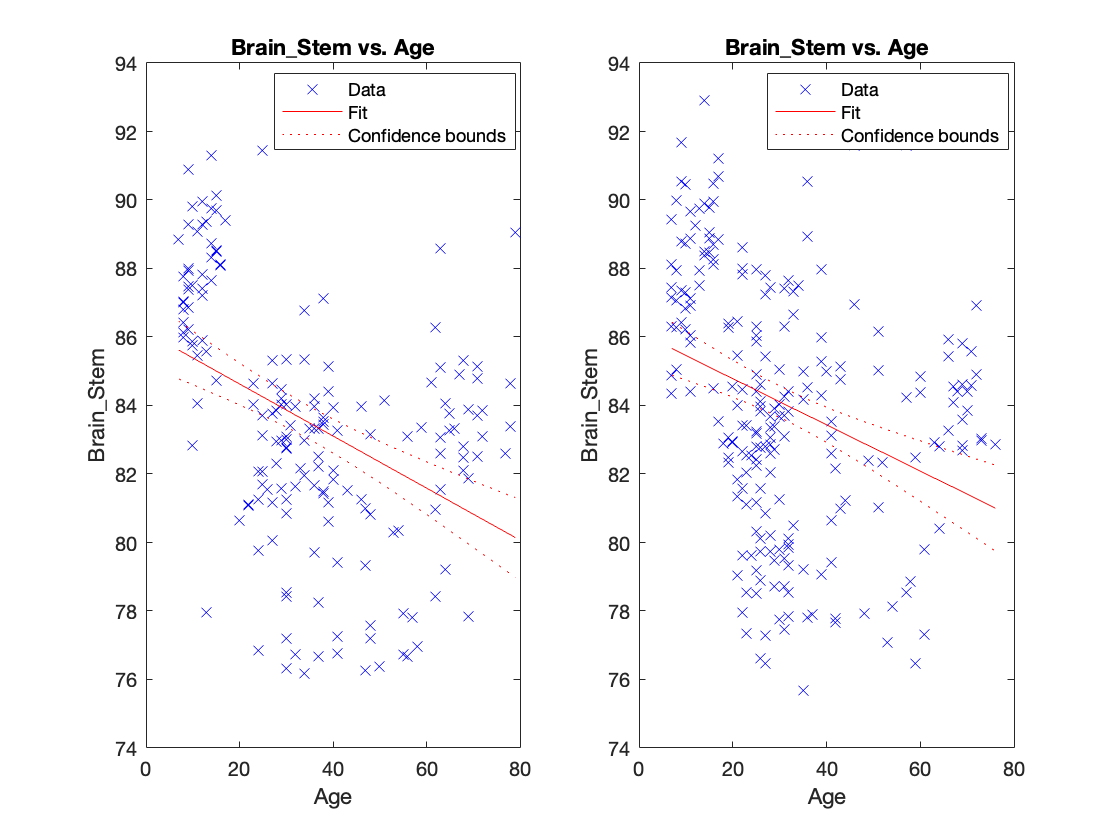

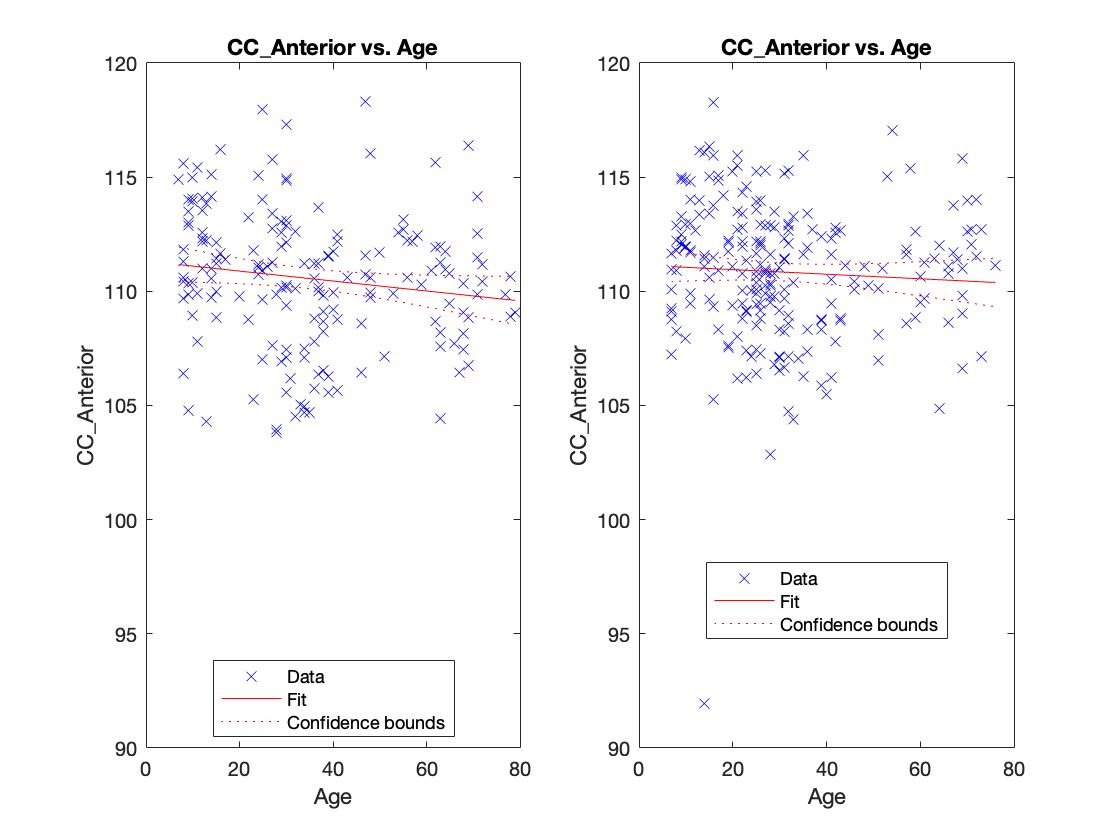

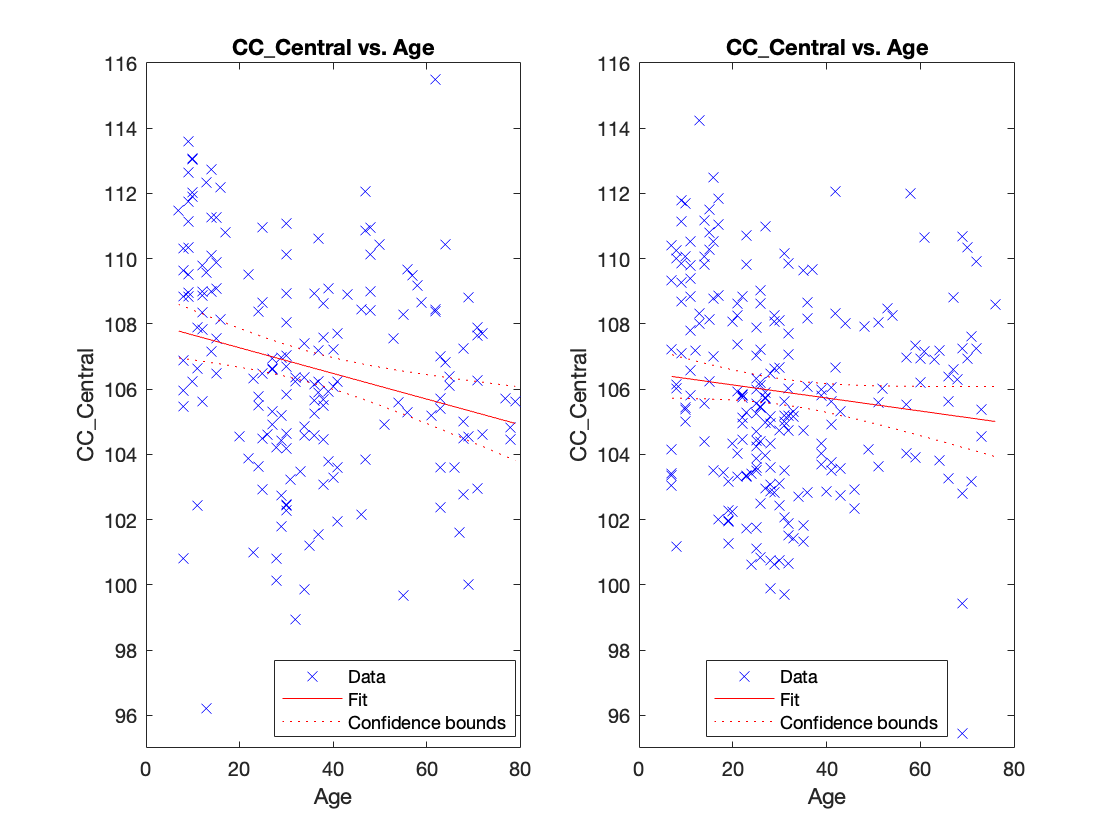

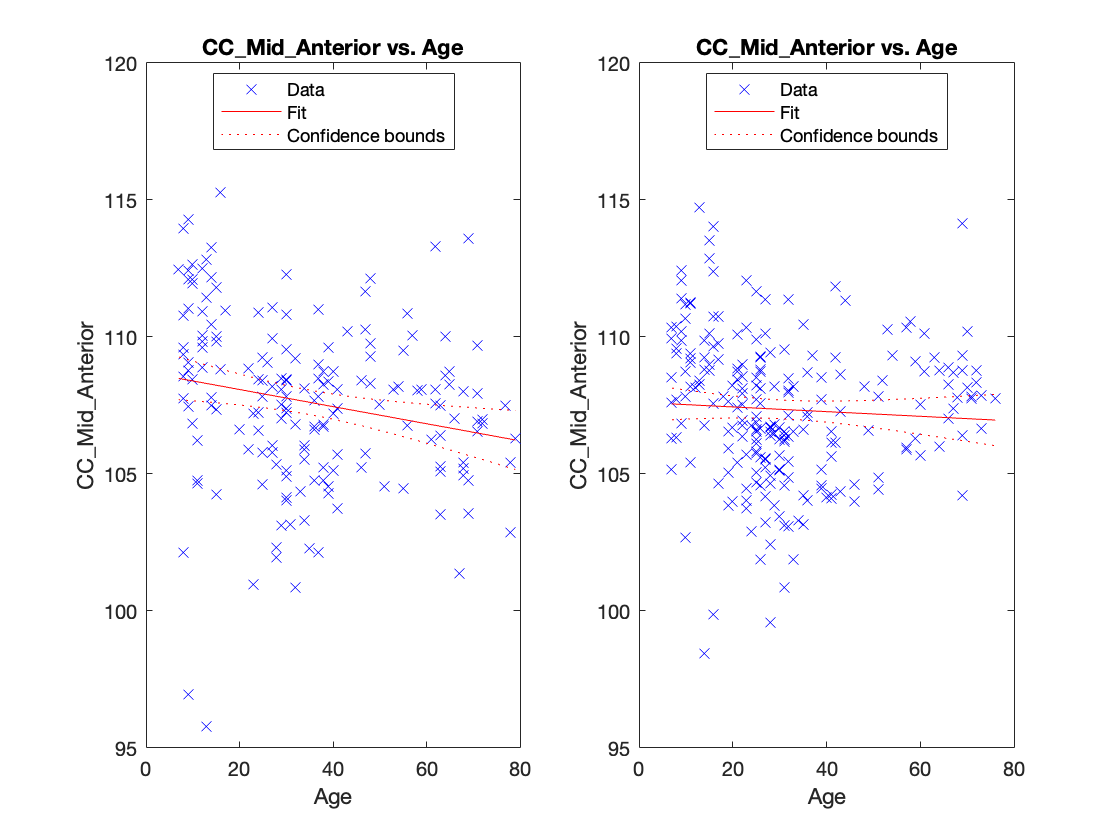

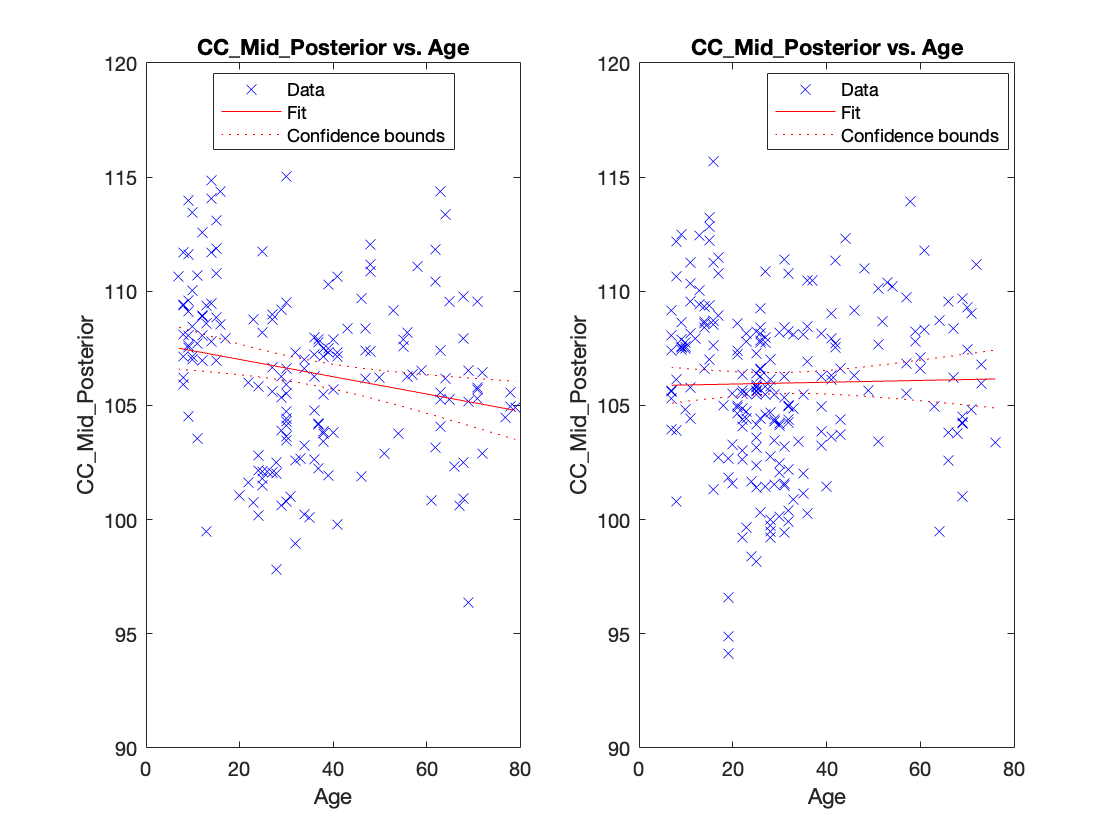

for idx = 1:5 %numel(plotcols)
    col = plotcols(idx);
    male_mdl = fitlm(measurements(measurements.Sex == "m", :), string(col) + " ~ Age");
    female_mdl = fitlm(measurements(measurements.Sex == "f", :), string(col) + " ~ Age");
    figure;
    ax_male   = subplot(1,2,1); 
    plot(male_mdl);
    ax_female = subplot(1,2,2); 
    plot(female_mdl);
    linkaxes([ax_male, ax_female], 'y');
end

Check the age distribution for males and females (for example with a boxplot)